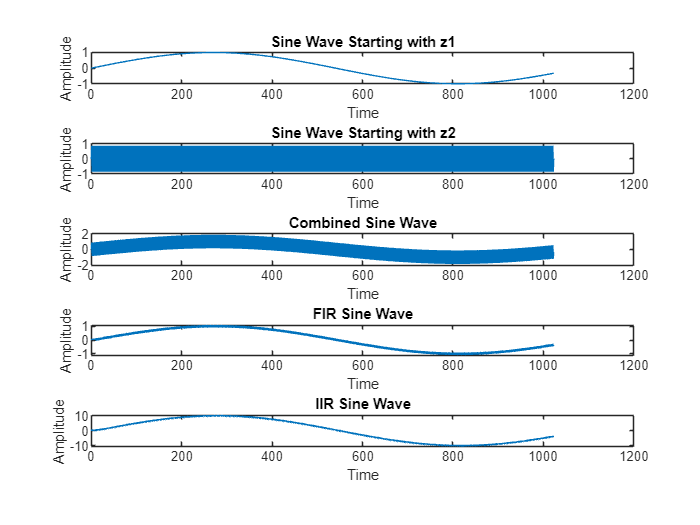

% Define z1 and z2
z1 = cos(2 * pi / 1080) + 1i * sin(2 * pi / 1080);
z2 = cos(2 * pi / 3) + 1i * sin(2 * pi / 3);

% Generate time array
N = 2^10; % Number of samples
t = 0:(N - 1); % Time array

% Generate sine waves starting with z1 and z2
sin_wave_z1 = sin(angle(z1) * t);
sin_wave_z2 = sin(angle(z2) * t);

% Construct the new signal by adding the sine waves together
new_sin_wave = sin_wave_z1 + sin_wave_z2;

% Apply FIR filter to the new sine wave 
M = 10;
fir_b = (1/M)*ones(1,M);
fir_a = 1;
fir_sin_wave = filter(fir_b, fir_a, new_sin_wave);

% Apply IIR filter to the new sine wave
iir_b = 1;
iir_a = [1 -0.9];
iir_sin_wave = filter(iir_b, iir_a, new_sin_wave);

% Calculate the spectrum using FFT
spectrum = fft(new_sin_wave);
fir_spectrum = fft(fir_sin_wave);
iir_spectrum = fft(iir_sin_wave);

% Plot the sine waves
figure;
subplot(5, 1, 1);
plot(t, sin_wave_z1);
title('Sine Wave Starting with z1');
xlabel('Time');
ylabel('Amplitude');

subplot(5, 1, 2);
plot(t, sin_wave_z2);
title('Sine Wave Starting with z2');
xlabel('Time');
ylabel('Amplitude');

subplot(5, 1, 3)
plot(t, new_sin_wave)
title('Combined Sine Wave');
xlabel('Time');
ylabel('Amplitude');

subplot(5, 1, 4)
plot(t,fir_sin_wave)
title('FIR Sine Wave');
xlabel('Time');
ylabel('Amplitude');

subplot(5, 1, 5)
plot(t,iir_sin_wave)
title('IIR Sine Wave');
xlabel('Time');
ylabel('Amplitude');

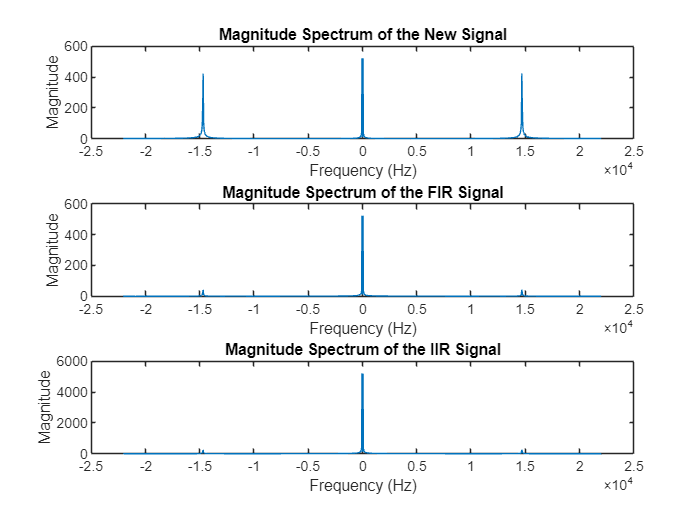

% Plot the magnitude spectrum
fs = 44100; % Sampling frequency
frequencies = fs/N*(-N/2:N/2-1);

figure;
subplot(3,1,1);
plot(frequencies, abs(fftshift(spectrum)));
title('Magnitude Spectrum of the New Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(3,1,2);
plot(frequencies, abs(fftshift(fir_spectrum)));
title('Magnitude Spectrum of the FIR Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(3,1,3);
plot(frequencies, abs(fftshift(iir_spectrum)));
title('Magnitude Spectrum of the IIR Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');